# Tutorial: Accessing Neuropixels Electrophysiology Data from the Allen Brain Observatory

This tutorial demonstrates access and basic analysis of the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2]. This public dataset consists of muti-channel electrophysiology ("ephys") experimental recordings, obtained using Neuropixels neural probe technology [3] from the primary visual cortex. 

### About the Brain Observatory Toolbox (BOT)

The BOT is a MATLAB toolbox for accessing, manipulating and analysing neurophysiology data from the Allen Brain Observatory. The BOT consists of functions and classes, contained within its top-level [package folder](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html) +bot, which are referenced from MATLAB with the prefix `bot`. The BOT provides convenient methods for identifying data sets of interest, and manages downloading and caching of data from the Allen Brain Observatory.

### The Visual Coding Neuropixels Data

The Neuropixels dataset contains extracellular electrophysiology data obtained using high-density Neuropixels probes placed in different regions of the mouse brain (for a complete listing see the technical white paper on the Allen Institute's Mouse Common Coordinate Framework [[4]](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2)). Neural activity from the cortex and thalamus was recorded during passive visual stimulation. Further details regarding stimuli can be found in the Allen Institute's technical white paper [[5]](https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf). 

The data was pre-processed using [standard procedures](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html#data-processing) and saved using [Neurodata Without Borders (NWB)](https://www.nwb.org/) file formats. Neural activity from each channel was saved in two streams 

- A high pass (analog 500 Hz and digital 150 Hz) filtered 'spike band' digitized at 30 kHz (Spikes were sorted using the MATLAB package Kilosort2 and quality metrics computed)

- A low pass (analog 1kHz and digital 625 Hz) filterted 'LFP band' digitized at 2.5 kHz and re-referenced for common noise rejection.

The data is described by several tables containing metadata whereas the actual data is stored in NWB files. Running this demo requires a total of 5GB of data to be downloaded which might take some time the first time. However, the data is then cached by this toolbox making subsequent runs faster. Metadata stored in tables is used to pre-select the data required for an analysis following which, only the minimum required actual data from NWB files is accessed. 

The Neuropixels data is grouped and organized by several ***linked dataset items*** of different types - experimental `sessions`, containing data from several `probes` which, in turn, contain data from multiple `channels` and `units`. S`essions`, `probes`, `channels` and `units` are shown schematically below.

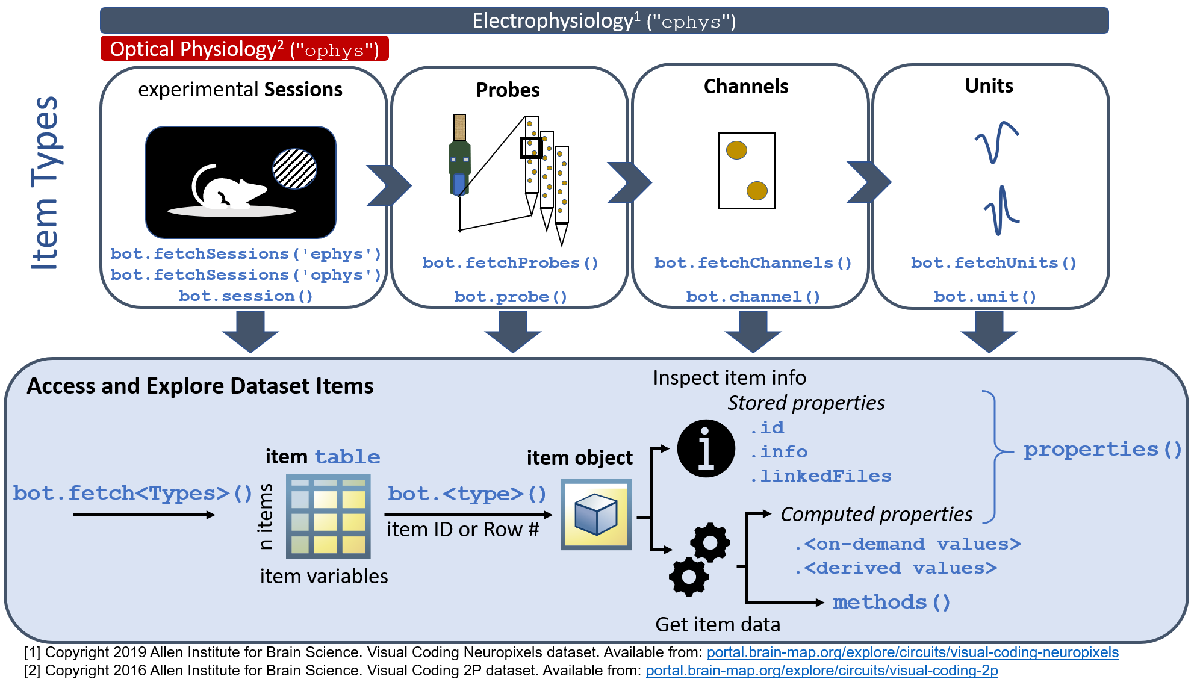

### Accessing the Visual Coding Neuropixels Dataset

Each dataset item type can be accessed using the `bot.fetch``LinkedDatasetItemType``()` functions. For example, `bot.fetchSessions('ephys')` retrieves a table of available EPhys experimental sessions. To access probes, channels or units instead of sessions, use `bot.fetchProbes()`, `bot.fetchChannels(),` and `bot.fetchUnits()` respectively.

Information regarding all dataset items of a particular type are available as tables. An individual dataset item can be queried from the table (using the row) or as an object (using the item id). For example, `bot.session(session_id)` retrieves a single experimental session. Objects come with properties used to inspect information related to that particular dataset item or methods for fetching or analyzing data linked to that particular dataset item.

availSessions = bot.fetchSessions('ephys');
availProbes = bot.fetchProbes();
availChannels = bot.fetchChannels();
availUnits = bot.fetchUnits();

Collectively the retrieved table arrays represent a manifest of the available dataset items organized at varying levels of hierarchy:

- experimental ephys **sessions** 

- associated Neuropixels **probes***, *which recorded ephys data during these sessions

- associated Neuropixels **channels***, *with recorded ephys data physically located along these probes

- inferred neuronal sources, known as **units**, computationally extracted from these channel recordings (via the Visual Coding Neuropixels data processing pipeline [1])

Inspecting the size of these table arrays with the command `whos` reveals the dataset is quite extensive:

whos availSessions availProbes availChannels availUnits

  Name                    Size                 Bytes  Class    Attributes

  availChannels      123224x29            1662965137  table              
  availProbes           332x23               4513037  table              
  availSessions          58x15                800331  table              
  availUnits          40010x51             546647719  table              



These dataset content tables consists of rows of dataset items whose column-oriented variables contain individual item information. Since tables are inherently two-dimensional, their size can also be expressed by their height (number of rows) and width (number of columns). Here the command `height` returns the number of dataset items for a given type: 

disp("There are " + height(availSessions) + " available sessions in the Visual Coding Neuropixels dataset")

There are 58 available sessions in the Visual Coding Neuropixels dataset


The Visual Coding Neuropixels dataset consists of dozens of experimental sessions, with recordings from hundreds of probes, which capture activity from tens of thousands of inferred neuronal units.

### Examining Sessions

Each session organizes data from the electrophysiology experiments and is a continuous, distinct recording period [[6]](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html).

#### Inspecting Available Sessions 

The `head` command can be used to inspect a table's structure via its first few rows. Let's inspect the available experimental sessions:

head(availSessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

Session information is returned as a table. Columns correspond to session parameters.

#### Selecting Sessions of Interest

Table [indexing operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) can be used to select specific experimental sessions (rows) with attributes of interest (column values). For instance, by combining [dot notation with logical indexing](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#mw_77d04ebd-b6f7-4ee9-93ac-1cc1fd7bc735), we can extract ("filter") sessions with female wild-type subjects that were presented a visual stimulus set designed for investigation of functional connectivity between brain regions [1]: 

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);
% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);
% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                              ephys_structure_acronyms                                              isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    _______________________________________________________________________________

From the October 2019 data release, three sessions are found matching the specified attributes of interest. 

#### Creating Session Objects

The Brain Observatory Toolbox defines [classes](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html) to represent individual Visual Coding Neuropixels dataset items as [objects](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html). These objects can inspected and worked with via their defined [properties and methods](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html).

A set of top-level functions (`bot.session`, `bot.probe`, `bot.channel`, `bot.unit)` are provided to create object arrays for dataset items of the corresponding content type. In the BOT, all experimental data are represented by summaries, with loading of large data files (slow) performed only when necessary. The `bot.session` function can be called to create an object representing the first session item in the `filteredSessions` table above:

These factory functions also can be supplied with a table array, whose rows will be converted to object array elements. For instance, create an object for the first session in `filteredSessions` via table indexing:

sessionUnderStudy = bot.session(filteredSessions(1,:)); 

The object has a property `info` providing a [structure](https://www.mathworks.com/help/matlab/ref/struct.html) (field-wise) representation of the values from the table row. This `info `property can be accessed via dot notation: 

sessionUnderStudy.info

ans = struct with fields:
                          id: 819186360
                  unit_count: 531
               channel_count: 1696
                 probe_count: 5
                session_type: functional_connectivity
                 age_in_days: 128
           fail_eye_tracking: 0
                         sex: F
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "APN; CA1; CA3; DG; HPF; LGd; LP; MB; NOT; POL; SCig; SCiw; SCop; SUB; VISam; VISl; VISpm; VISrl"
           isi_experiment_id: 809373390
         date_of_acquisition: 08-Feb-2019 09:02:25
                 specimen_id: 800249587
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


#### Inspecting Session Object Properties

Display the `sessionUnderStudy` object to see its full set of properties, which can provide further access into its underlying data. Scroll through the displayed output to inspect the full set:

disp(sessionUnderStudy)

  ephyssession with properties:

                              info: [1×1 struct]
                                id: 819186360
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: [1×18 string]

   Linked Items
                            probes: [5×23 table]
                          channels: [1696×29 table]
                             units: [531×51 table]

   Linked Item Derived Values


       channel_structure_intervals: [34×2 table]
         structurewise_unit_counts: [15×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_detailed: '[on demand]'
                      rig_metadata: '[on demand]'
                     running_speed: '[on demand]'
                session_start_time: '[on demand]'
                  spike_amplitudes: '[on demand]'
                       spike_times: '[on demand]'
               stimulus_conditions: '[on demand]'
                   stimulus_epochs: '[on demand]'
                    stimulus_names: '[on demand]'
            stimulus_presentations: '[on demand]'

   Linked File Values ('StimTemplatesGroup')
                stimulus_templates: '[on demand]'



The `session` object collects a number of useful properties for inspection. These include:

- Information about this session (`.info`), obtained from the table row used to create this session object

- Values derived from the item information (`Info Derived Values`)

- Tables summarizing items (probes, channels, units) linked to this session (`Linked Items`) 

- Values derived from the linked item tables (`Linked Item Derived Values`)

- Values obtained from the files linked to this session (nicknamed "`SessNWB" and "StimTemplatesGroup"`)

The `SessNWB `properties are linked to the Neurodata without Borders file for this session. Accessing these properties will download the file or load the file contents from the cache. Many of these data files are several GB in size, causing the first-time download to be time-consuming. 

*Linked Items *properties contain pre-filtered tables for the probe, channel, and unit items that correspond to this experimental session. Linked items can be accessed via the `.<LinkedItems>` property. This session included recordings from 5 probes. Given the high density of Neuropixels ephys probes (384 channels each) [3], these contain 1696 channels with unit data, from which 531 neuronal units were inferred.

*Linked Item Derived Values* properties contain computed metrics derived from the linked items, such as number of units associated with each brain structure recorded.

sessionUnderStudy.structurewise_unit_counts 

ans = 15×2 table
    ephys_structure_acronym    count
    _______________________    _____

             VISrl              107 
             LP                  78 
             VISl                72 
             CA1                 65 
             VISam               52 
             LGd                 34 
             DG                  28 
             APN                 23 
             VISpm               20 
             SCig                18 
             CA3                 17 
             POL                  6 
             SUB                  5 
             NOT                  4 
             SCiw                 2 


*Linked File Values* properties represent direct and computed data values from the underlying data file(s) for the session and would require these data files to be downloaded. Since the Allen Brain Observatory data files, which are in Neurodata without Borders neurophysiology (NWB:N) format [[7]](https://www.biorxiv.org/content/10.1101/523035v1), can be quite large (sometimes in the GB range), the download is deferred ("on demand") until the property is accessed. 

### Group Analysis of Session Units

The units are computed and are scientifically valuable dataset items provided by the Allen Brain Observatory web resource, allowing some scientific group analysis to be performed without downloading underlying NWB:N data files. 

Access and inspect the table of units linked to the `sessionUnderStudy:`

unitsTable = sessionUnderStudy.units;
head(unitsTable)

ans = 8×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

The units metadata (columns) contains further computed quantities such as the spike firing rate of the inferred neuron. Use `summary` to compute summary statistics across the hundreds of units in the `sessionUnderStudy:`

summary(unitsTable(:,"firing_rate"));

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 531×1 double

        Values:

            Min       0.096779
            Median      5.4277
            Max         46.996



The spike firing rate for the inferred neurons varies over a large range from nearly 0 Hz to nearly 50 Hz. A histogram plot can be used to visualize the statistical distribution:

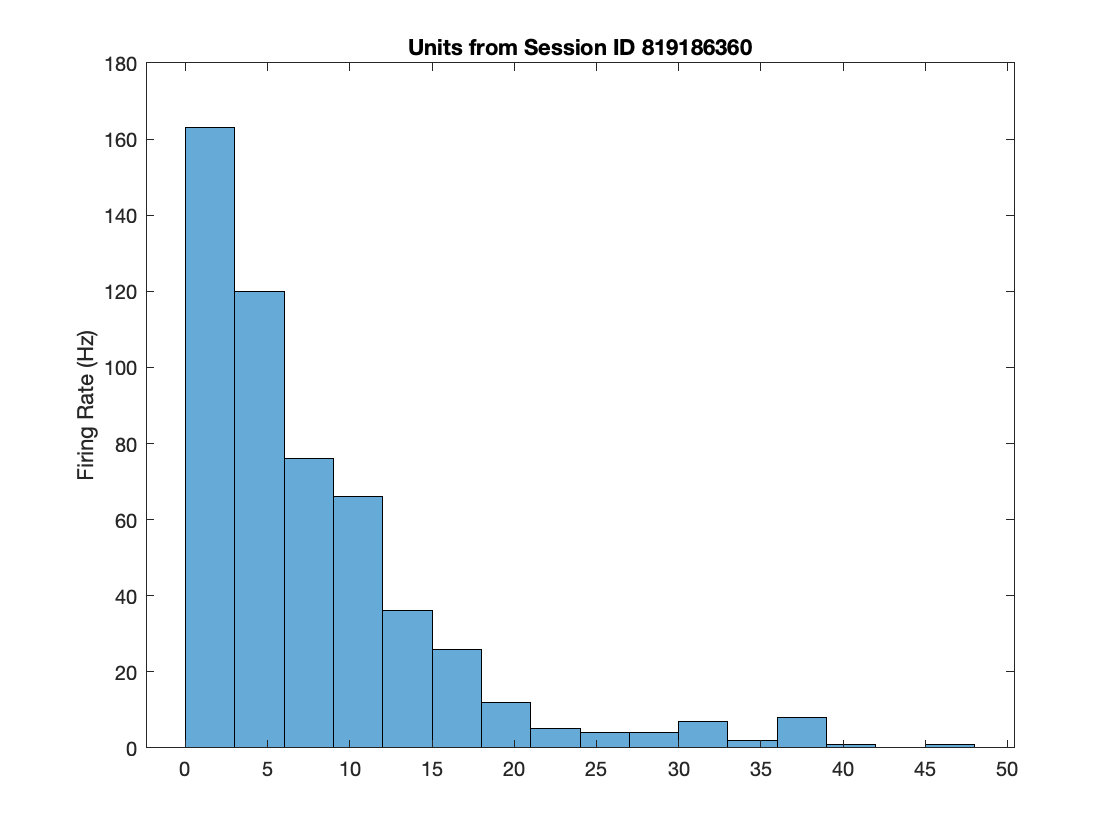

histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');
title("Units from Session ID " + sessionUnderStudy.id);

The majority of units had firing rates < 10Hz, while the high firing rate units (>30 Hz) form a slightly elevated fraction in the distribution tail for this `sessionUnderStudy`.

### Examining Probes

In addition to high frequency data capturing spikes, low frequency data capturing slow oscillations were also recorded from individual probes. To retrieve all the probes in a session, `.probes` can be used.

probes = sessionUnderStudy.probes;

A `probes` table row is used to pick a probe to construct a probe object using the `bot.probe()` function.

% obtain a `probe` object for the first probe
probe = bot.probe(probes(1, :))

probe =   ephysprobe with properties:

           info: [1×1 struct]
             id: 820311754
    linkedFiles: [1×1 table]

   Linked Items
        session: [1×1 bot.item.ephyssession]
       channels: [345×29 table]
          units: [81×51 table]

   Linked File Values ('LFPNWB')
        lfpData: '[on demand]'
        csdData: '[on demand]'


Information about the `probe` object can be accessed:

fieldnames(probe.info)

ans = 23×1 cell array
    {'id'                             }
    {'ephys_session_id'               }
    {'unit_count'                     }
    {'channel_count'                  }
    {'name'                           }
    {'session_type'                   }
    {'age_in_days'                    }
    {'air_channel_index'              }
    {'fail_eye_tracking'              }
    {'has_lfp_data'                   }
    {'lfp_sampling_rate'              }
    {'lfp_temporal_subsampling_factor'}
    {'phase'                          }
    {'sampling_rate'                  }
    {'sex'                            }
    {'surface_channel_index'          }
    {'genotype'                       }
    {'ephys_structure_acronyms'       }
    {'isi_experiment_id'              }
    {'date_of_acquisition'            }
    {'specimen_id'                    }
    {'specimen'                       }
    {'well_known_files'               }


#### Probe Low Frequency Data

Now, methods from the `probe` object can be used to obtain the local-field potential (LFP) and current-source density (CSD) measurements that access the low frequency data. These measurements are in the form of linked file values.

To access LFP data, the `.lfpData` property can be used, and the return value is a timetable of times and local field potentials.

lfpTimetable = probe.lfpData;
head(lfpTimetable)

ans = 8×1 timetable
       Time       LocalFieldPotential
    __________    ___________________

    3.6356 sec       [1×77 single]   
    3.6364 sec       [1×77 single]   
    3.6372 sec       [1×77 single]   
    3.638 sec        [1×77 single]   
    3.6388 sec       [1×77 single]   
    3.6396 sec       [1×77 single]   
    3.6404 sec       [1×77 single]   
    3.6412 sec       [1×77 single]   


To access CSD measurements, the `.csdData` property can be used, and the return value is a struct consisting of a timetable, horizontal positions, and vertical positions.

probe.csdData

ans = struct with fields:
                   data: [875×1 timetable]
    horizontalPositions: [384×1 double]
      verticalPositions: [384×1 double]


### Examining Channels

To retrieve all the channels in a session, `.channels` can be used:

channels = sessionUnderStudy.channels;

A `channels` table row is used to pick a channel to construct a channel object using the `bot.channel()` function.

% obtain a `channel` object for the first channel
channel = bot.channel(channels(1, :))

channel =   ephyschannel with properties:

       info: [1×1 struct]
         id: 849795978

   Linked Items
    session: [1×1 bot.item.ephyssession]
      probe: [1×1 bot.item.ephysprobe]
      units: [1×51 table]


Information about the `channel` object can be accessed:

fieldnames(channel.info)

ans = 29×1 cell array
    {'id'                               }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'unit_count'                       }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'anterior_posterior_ccf_coordinate'}
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'has_lfp_data'                     }
    {'left_right_ccf_coordinate'        }
    {'lfp_sampling_rate'                }
    {'lfp_temporal_subsampling_factor'  }
    {'local_index'                      }
    {'phase'                            }
    {'probe_horizontal_position'        }
    {'probe_name'                       }
    {'probe_vertical_position'          }
    {'sampling_rate'                    }
    {'sex'                              }
    {'surface_channel_index'            }
    {'genoty

### Examining Units

To retrieve all the units in a session, `.units` can be used. Units from a specific area, such as the anteromedial (AM) area of the primary visual cortex, can now be filtered and selected. 

units = sessionUnderStudy.units;
units = units(units.ephys_structure_acronym == 'VISam', :)

units = 52×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

A `units` table row, or `unit_id` of interest, is used to pick a unit to construct a unit object using the `bot.unit()` function.

% obtain a `unit` object for the first unit
unit = bot.unit(units(1, :))

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 951133559

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]



% or alternatively:
unit = bot.unit(units{1, 'id'})

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 951133559

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


The `unit` object holds references to the `session`, `probe` and `channel` that it belongs to, as well as information about this unit:

fieldnames(unit.info)

ans = 51×1 cell array
    {'id'                               }
    {'ephys_channel_id'                 }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'L_ratio'                          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'amplitude_cutoff'                 }
    {'anterior_posterior_ccf_coordinate'}
    {'cumulative_drift'                 }
    {'d_prime'                          }
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'firing_rate'                      }
    {'has_lfp_data'                     }
    {'isi_violations'                   }
    {'isolation_distance'               }
    {'left_right_ccf_coordinate'        }
    {'lfp_temporal_subsampling_factor'  }
    {'max_drift'                        }
    {'nn_hit_rate'                      }
    {'nn_mis

For example, to access the particular probe object associated with the unit, `unit.probe` can be used.

### References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[3] Information about Neuropixels probes available at [https://neuropixels.org](https://neuropixels.org).

[4] Copyright 2017 Allen Institute for Brain Science. Technical White Paper on the Mouse Common Coordinate Framework. Available from: [http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2).

[5] Copyright 2019 Allen Institute for Brain Science. Technical White Paper on the Visual Coding Neuropixels dataset. Available from: [https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf](https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf).

[6] [https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html.](https://allensdk.readthedocs.io/en/latest/_static/examples/nb/ecephys_session.html.) 

[7] Rubel et al. NWB:N 2.0: An Accessible Data Standard for Neurophysiology. [https://www.biorxiv.org/content/10.1101/523035v1](https://www.biorxiv.org/content/10.1101/523035v1).